clear;
rng(1)

% Load dataset
datasetName = "dataset5";
files = getDataset(collectMetadata('DataSet/Faulty bearing'), datasetName);

% Get Phase Current Features
[X, Y, featureTables] = getCachedFeatures(files, datasetName, 1, 50);

[INFO] Checking cached features: ModelsData\Cache\features_dataset5_win1_ovlp50.mat
[INFO] Cache is valid. Loading features from cache.


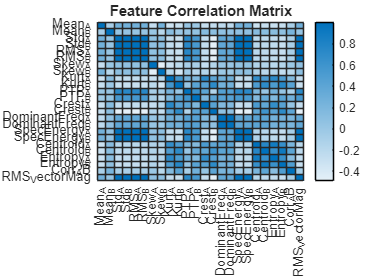

clear datasetName


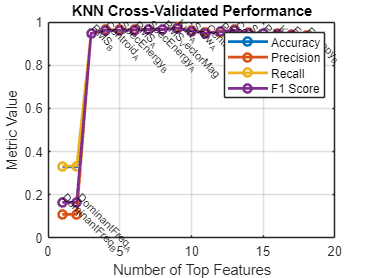

% Remove some features to test
featuresToRemove = ["Mean_A", "Mean_B", "Std_A", "Std_B", "Crest_A", "Crest_B"];
[X, ~] = excludeFeatures(X, featureTables, featuresToRemove);

% Define Parameters
K = 5; % Folds Num
cv = cvpartition(Y, 'KFold', K);

% X             - Feature matrix
% Y             - Labels (should be categorical)
% sortIdx       - Sorted feature indices (from RF)
% sortedFeatureNames - Names of features in sortIdx order
load("ModelsData\RF-feature-importance.mat");

Y = categorical(Y);
maxFeatures = length(sortIdx);
metrics_knn = zeros(maxFeatures, 4);  % Accuracy, Precision, Recall, F1

% Evaluate KNN with Feature Selection
for loopN = 1:maxFeatures
    loopIdx = sortIdx(1:loopN);  % Use top-N features
    loopAllYPred = [];
    loopAllYTrue = [];

    for loopFold = 1:K
        loopTrainIdx = training(cv, loopFold);
        loopTestIdx = test(cv, loopFold);

        loopXTrain = X(loopTrainIdx, loopIdx);
        loopYTrain = Y(loopTrainIdx);
        loopXTest = X(loopTestIdx, loopIdx);
        loopYTest = Y(loopTestIdx);

        % Train KNN
        loopModel = fitcknn(loopXTrain, loopYTrain, ...
            'NumNeighbors', 5, ...
            'Standardize', true);  % Normalize features

        loopYPred = predict(loopModel, loopXTest);

        loopAllYPred = [loopAllYPred; loopYPred];
        loopAllYTrue = [loopAllYTrue; loopYTest];
    end

    % === Metrics ===
    loopConf = confusionmat(loopAllYTrue, loopAllYPred);
    loopTP = diag(loopConf);
    loopFP = sum(loopConf, 1)' - loopTP;
    loopFN = sum(loopConf, 2) - loopTP;

    loopPrecision = loopTP ./ (loopTP + loopFP + eps);
    loopRecall = loopTP ./ (loopTP + loopFN + eps);
    loopF1 = 2 * (loopPrecision .* loopRecall) ./ (loopPrecision + loopRecall + eps);

    metrics_knn(loopN, :) = [mean(loopAllYPred == loopAllYTrue), mean(loopPrecision), mean(loopRecall), mean(loopF1)];
end

% Plot and Annotate Metrics
figure;
plot(metrics_knn, '-o', 'LineWidth', 2);
legend('Accuracy', 'Precision', 'Recall', 'F1 Score');
xlabel('Number of Top Features');
ylabel('Metric Value');
title('KNN Cross-Validated Performance');
grid on;

% Annotate F1 curve with feature names
hold on;
for loopIdx = 1:maxFeatures
    text(loopIdx, metrics_knn(loopIdx, 4) + 0.03, sortedFeatureNames(loopIdx), ...
        'FontSize', 8, 'Rotation', -45, 'HorizontalAlignment', 'left');
end
hold off;


% Print Best Metrics + Features
metricNames = ["Accuracy", "Precision", "Recall", "F1 Score"];

for loopIdx = 1:4
    [loopBestVal, loopBestIdx] = max(metrics_knn(:, loopIdx));
    fprintf('Best %s: %.4f with %d features\n', metricNames(loopIdx), loopBestVal, loopBestIdx);
    disp(sortedFeatureNames(1:loopBestIdx)');
end

Best Accuracy: 0.9713 with 9 features


    "DominantFreq_B"
    "DominantFreq_A"
    "RMS_B"
    "Centroid_A"
    "SpecEnergy_B"
    "RMS_A"
    "SpecEnergy_A"
    "RMS_VectorMag"
    "Kurt_A"



Best Precision: 0.9727 with 9 features


    "DominantFreq_B"
    "DominantFreq_A"
    "RMS_B"
    "Centroid_A"
    "SpecEnergy_B"
    "RMS_A"
    "SpecEnergy_A"
    "RMS_VectorMag"
    "Kurt_A"



Best Recall: 0.9707 with 9 features


    "DominantFreq_B"
    "DominantFreq_A"
    "RMS_B"
    "Centroid_A"
    "SpecEnergy_B"
    "RMS_A"
    "SpecEnergy_A"
    "RMS_VectorMag"
    "Kurt_A"



Best F1 Score: 0.9713 with 9 features


    "DominantFreq_B"
    "DominantFreq_A"
    "RMS_B"
    "Centroid_A"
    "SpecEnergy_B"
    "RMS_A"
    "SpecEnergy_A"
    "RMS_VectorMag"
    "Kurt_A"



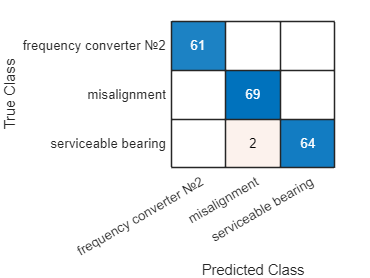

% Retrain Final Model and get results
% Split dataset by files
[isTrain, isTest, ~, ~] = equalFileSplit(featureTables.FileIndex, Y, 0.2);
loopXTrain = X(isTrain, :);
loopYTrain = Y(isTrain);
loopXTest  = X(isTest, :);
loopYTest  = Y(isTest);

[~, bestF1Idx] = max(metrics_knn(:, 4));
loopXTrain = loopXTrain(:, sortIdx(1:bestF1Idx));
loopXTest = loopXTest(:, sortIdx(1:bestF1Idx));

finalKNNModel = fitcknn(loopXTrain, loopYTrain, ...
    'NumNeighbors', 5, ...
    'Standardize', true);
% Confusion Chart
YPredTest = categorical(predict(finalKNNModel, loopXTest));
confusionchart(loopYTest, YPredTest);


% Get Wrong Predictions
wrongIdx = YPredTest ~= loopYTest;
testIndicesInFullTable = find(isTest);  % numeric indices of test rows
wrongIndicesInFullTable = testIndicesInFullTable(wrongIdx);
wrongPredictions = featureTables(wrongIndicesInFullTable, :);
wrongPredictions.TrueLabel = loopYTest(wrongIdx);
wrongPredictions.PredictedLabel = YPredTest(wrongIdx);

% Clean Up
clear loopConf cv loopF1 featureCorrMatrix featureNames featureNamesTable
clear featuresToRemove loopFN loopFP impMatrix isTest isTrain K
clear metricNames metrics_knn maxFeatures 
clear loopPrecision loopRecall retainedFeatures sortedFeatureNames sortedImportance sortIdx
clear testFiles testIndicesInFullTable loopTP trainFiles
clear wrongIdx wrongIndicesInFullTable loopXTest loopXTrain YPredTest loopYTest loopYTrain

vars = who;
loopVars = vars(startsWith(vars, 'loop'));
clear(loopVars{:});
clear loopVars vars
